%Main File

%Demo Model
n_population = 1000;
n_pod_size = 7;
n_time = 150;
M_airtight = zeros(n_population, n_population);
M_pod_n = ones(n_pod_size, n_pod_size) - eye(n_pod_size);

for i = 1:(ceil(n_population/n_pod_size))+1
    slice_begin = (i - 1) * n_pod_size + 1;
    slice_end = slice_begin + n_pod_size - 1;
    if slice_end > n_population
        slice_end = n_population;
        M_pod_n = ones((slice_end-slice_begin)+1, (slice_end-slice_begin)+1) - eye((slice_end-slice_begin)+1);
    end
    M_airtight(slice_begin:slice_end, slice_begin:slice_end) = M_pod_n;
end
M_airtight

M_airtight =      0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     0     0     0     0     0     0     0

Graph_airtight = graph(M_airtight)

Graph_airtight =   graph with properties:

    Edges: [2997×2 table]
    Nodes: [1000×0 table]


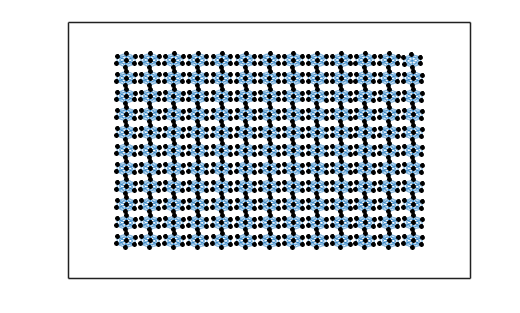

figure(); 
h = plot(Graph_airtight, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')